# EEG processing for NF systems

Jorge Ethan Mc Kelligan Desilos - A01412313

Marián Pérez Cerecedo - A01412386

Andrés Eduardo García Sáenz - A015633674

Sergio Romero Martínez - A01781725

**Instrucciones: **

1. Use one EEG recording that you and your team recorded in the lab, and that is related to your challenge. The recording must be of at least 3 minutes, and it must include two different conditions (e.g. rest, attention, meditation, etc...). Alternatively, you can use an EEG signal from a database, but with the same duration, and conditions criteria. The experimental conditions must be related to your challenge.

2. Load your signal into EEGLAB, and show the sample rate, number of channels, and duration of your recording. 

3. Use a band-pass filter to remove drift, and powerline noise. Specify the frequency ranges used and explain your choice. 

4. Estimate the neuromarker (across time) you are interested in monitoring for your NF system, for all the duration of your EEG recording. Explain why and how you estimated such neuromarker. Also, if your neuromarker is the result of the combination of multiple channels, explain this process as well. 

5. Generate a report to document the previous steps, including a conclusion related to this analysis in the context of your challenge. Also make sure to include the following figures: 

(1) Raw EEG signals (across time), identifying the times of each condition. 

(2) EEG signals (across time) after the band-pass filter, identifying the times of each condition. 

(3) Neuromarker (across time), identifying the times of each condition. 

**Base de datos**:  [https://ieee-dataport.org/open-access/dasps-database ](https://ieee-dataport.org/open-access/dasps-database)

Las condiciones que presenta son los siguientes

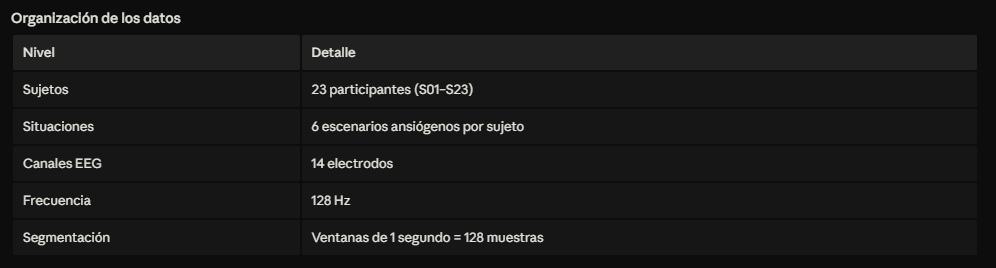

fs = 128;
%Datos del paciente uno
path = 'Raw data mat/S01.mat';
paciente_1_mat = load(path); %struct. Tambien lo tenemos con las grabaciones seguidas 
labels = paciente_1.labels

labels =      1     8
     1     8
     3     8
     3     8
     1     8
     1     8
     3     5
     3     5
     3     6
     3     6
     1     7
     1     7


valence = labels(:, 1);
arousal = labels(:, 2);

% grabaciones impar significa cuando recitaba el psicologo la situacion de
% estres, grabaciones par cuando la persona recitaba lo que se le conto
datos_p1 = paciente_1.data;
size(datos_p1)

ans =           14        1920          12


El tamaño es de 14 eelctrodos x 1920 x 12 

- 14 derivaciones

- 1920 muestras = 15 seg

- Las 6 situaciones con fases 

- Escucha: par

- Recall: impar

Para usar eeglab correctamente contrajimos las 12 situaciones en una lectura seguida 

Pasamos de 12 grabaciones de 1920 muestras => 15 segundos

Una sola grabacion de 23040 muestras => 3 minutos

EEG = pop_loadset('C:\Users\jorge\Documents\Tec\Uni\6. Sexto Semestre\EEG_Luzma\EEG processing for NF systems\S01_eeglab.set') 

pop_loadset(): loading file C:\Users\jorge\Documents\Tec\Uni\6. Sexto Semestre\EEG_Luzma\EEG processing for NF systems\S01_eeglab.set ...


EEG = struct with fields:
             setname: ''
            filename: 'S01_eeglab.set'
            filepath: 'C:\Users\jorge\Documents\Tec\Uni\6. Sexto Semestre\EEG_Luzma\EEG processing for NF systems'
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: ''
              nbchan: 14
              trials: 1
                pnts: 23040
               srate: 128
                xmin: 0
                xmax: 179.9922
               times: [0 7.8125 15.6250 23.4375 31.2500 39.0625 46.8750 54.6875 62.5000 70.3125 78.1250 85.9375 93.7500 101.5625 109.3750 117.1875 125 132.8125 140.6250 148.4375 156.2500 164.0625 171.8750 179.6875 187.5000 195.3125 … ] (1×23040 double)
                data: [14×23040 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×14 struct]
          urchanlocs: []
            chaninfo: [1×1 struct

%Misma funcion que usa la GUI de eeglab, pero para script

Se pueden ver claramente los 14 canales

chan_num = EEG.nbchan

chan_num = 14

Canales nombres

chan_names = EEG.chanlocs

chan_names = 1×14 struct array with fields:
    labels
    ref
    theta
    radius
    X
    Y
    Z
    sph_theta
    sph_phi
    sph_radius
    type


El f3 es el 3 y el f4 es el 12

Sampling rate

fs = EEG.srate

fs = 128

La duracion es de 3 minutos. 6 historias con dos estados. Escuchando el relato del psicologo, recitandolo en su mente.

samples = EEG.pnts

samples = 23040

seconds = samples / fs

seconds = 180

minutes = seconds / 60

minutes = 3

%Filtrado de señal
% Filtro pasa-bandas 1-45 Hz, elimina el drift y la señal de europa como de
% america. las ondas de interes (alpha) siguen estando presentes para el
% analisis. 
EEG_filt = pop_eegfiltnew(EEG, 1, 45); %Es la misma funcion que usa la GUI de eeglab

pop_eegfiltnew() - performing 425 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.99622641509434 Hz
pop_eegfiltnew() - passband edge(s): [1 45] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.50188679245283 45.4981132075472] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EEG_filt = eeg_checkset(EEG_filt);

Fourier de la señal filtrada y no filtrada

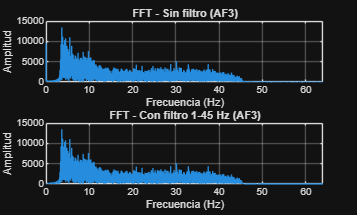

N  = EEG.pnts;
fs = EEG.srate;
f  = (0:N/2) * (fs/N);   % eje de frecuencia en Hz (solo positivo)

fourier_og  = abs(fft(EEG.data(1,:)));
fourier_new = abs(fft(EEG_filt.data(1,:)));

% Solo mitad positiva del espectro
mag_og  = fourier_og(1:N/2+1);
mag_new = fourier_new(1:N/2+1);

figure;
subplot(2,1,1);
plot(f, mag_og);
xlabel('Frecuencia (Hz)'); ylabel('Amplitud');
title('FFT - Sin filtro (AF3)');
xlim([0 64]); grid on;

subplot(2,1,2);
plot(f, mag_new);
xlabel('Frecuencia (Hz)'); ylabel('Amplitud');
title('FFT - Con filtro 1-45 Hz (AF3)');
xlim([0 64]); grid on;

Podemos ver que si habia ruido de DC en 0 hz, pero no de linea (50-60 hz). Igualmente mejora la calidad. Probablemente por filtro interno del eeg que rechaza bandas que no nos son utiles en EEG.

% Colores
color_listen = [0.2  0.6  0.9];
color_recall = [0.6  0.8  0.3];
t_axis = (0:EEG.pnts-1) / EEG.srate;
ch_names = {EEG.chanlocs.labels};
offset = 150;

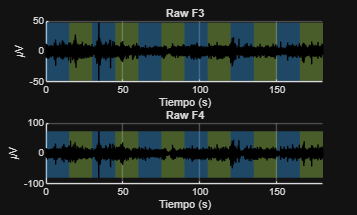

t_axis = (0:EEG.pnts-1) / EEG.srate;
cl = [0.2 0.6 0.9];  cr = [0.6 0.8 0.3];   % Listen / Recall
raw  = EEG.data([3 12], :);
filt = EEG_filt.data([3 12], :);
ch_names = {'F3','F4'};

% --- Shading helper (reutilizado en las 3 figuras) ---
function shade(cl, cr, ylo, yhi)
    for i = 1:12
        fill([(i-1)*15 i*15 i*15 (i-1)*15],[ylo ylo yhi yhi], ...
             cl*(mod(i,2)==1)+cr*(mod(i,2)==0), ...
             'EdgeColor','none','FaceAlpha',0.4,'HandleVisibility','off');
    end
end

% --- Fig 1: Crudo ---
figure('Name','Raw F3 & F4');
for k = 1:2
    subplot(2,1,k); hold on;
    shade(cl, cr, min(raw(k,:)), max(raw(k,:)));
    plot(t_axis, raw(k,:), 'k', 'LineWidth', 0.6);
    title(['Raw ' ch_names{k}]); xlabel('Tiempo (s)'); ylabel('\muV');
    xlim([0 180]); grid on; hold off;
end

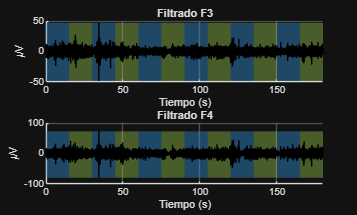


% --- Fig 2: Filtrado ---
figure('Name','Filtered F3 & F4');
for k = 1:2
    subplot(2,1,k); hold on;
    shade(cl, cr, min(filt(k,:)), max(filt(k,:)));
    plot(t_axis, filt(k,:), 'k', 'LineWidth', 0.6);
    title(['Filtrado ' ch_names{k}]); xlabel('Tiempo (s)'); ylabel('\muV');
    xlim([0 180]); grid on; hold off;
end

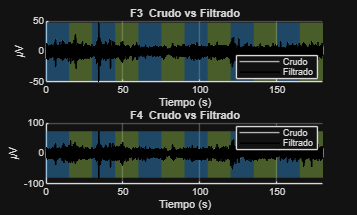



% --- Fig 3: Overlay crudo vs filtrado ---
figure('Name','Raw vs Filtered');
for k = 1:2
    subplot(2,1,k); hold on;
    shade(cl, cr, min(raw(k,:)), max(raw(k,:)));
    hr = plot(t_axis, raw(k,:),  'Color', [0.7 0.7 0.7], 'LineWidth', 0.6);
    hf = plot(t_axis, filt(k,:), 'k', 'LineWidth', 1.2);
    hr.Color(4) = 0.4;
    title([ch_names{k} '  Crudo vs Filtrado']);
    xlabel('Tiempo (s)'); ylabel('\muV');
    xlim([0 180]); grid on;
    legend([hr hf],'Crudo','Filtrado','Location','best');
    hold off;
end

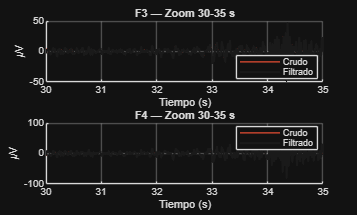


figure('Name','Raw vs Filtered - Zoom');
zoom_range = t_axis >= 30 & t_axis <= 35;   % 5 segundos

for k = 1:2
    subplot(2,1,k); hold on;
    hr = plot(t_axis(zoom_range), raw(k,zoom_range),  'Color',[0.9 0.3 0.2], 'LineWidth', 1.0);
    hf = plot(t_axis(zoom_range), filt(k,zoom_range), 'Color',[0.1 0.1 0.1], 'LineWidth', 1.5);
    hr.Color(4) = 0.6;
    title([ch_names{k} ' — Zoom 30-35 s']);
    xlabel('Tiempo (s)'); ylabel('\muV'); grid on;
    legend([hr hf],'Crudo','Filtrado','Location','best');
    hold off;
end

Como podemos ver en esta grafica el cambio despues del filtrado es muy sutil. pero si hay un cambio, porque como vimos en las graficas de fourier si habia potencia en frecuencia 0 hz. En el pdf exportado no se ve tambian asi que ademas adjunto una imagen

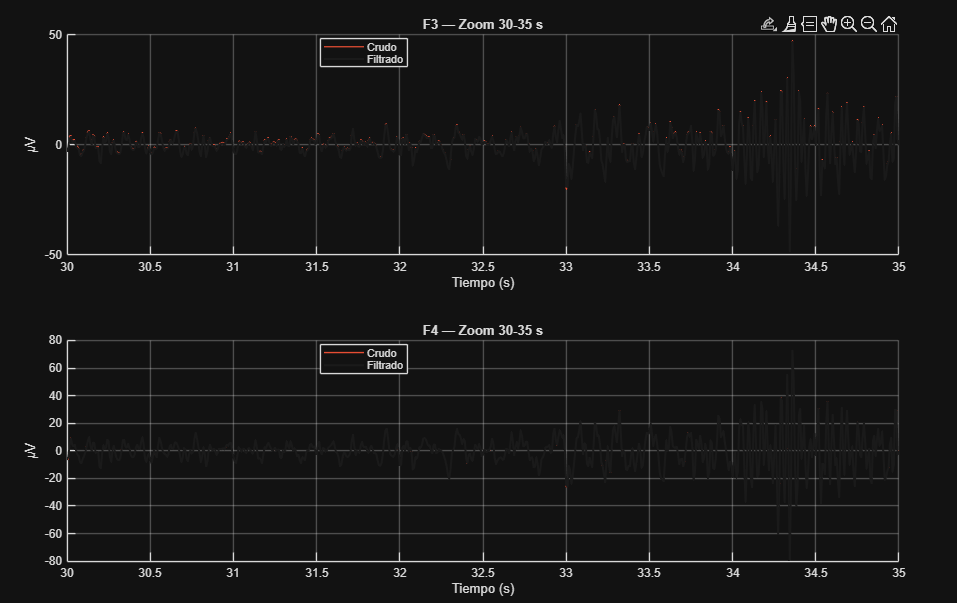

Frontal Alpha Assymetry

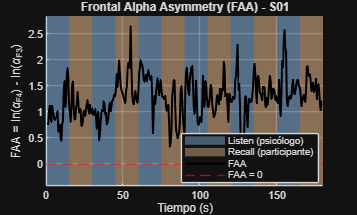

%% FAA Neuromarker — F3/F4
fs = EEG_filt.srate;
win_samp = round(2 * fs);
step_samp = round(0.5 * fs);
alpha_low = 8; alpha_high = 13;

data_F3 = EEG_filt.data(3, :);
data_F4 = EEG_filt.data(12, :);

n_samp = size(EEG_filt.data, 2);
time_faa = []; faa_values = [];

for t = 1:step_samp:(n_samp - win_samp + 1)
    [pxx_F3, f] = pwelch(data_F3(t:t+win_samp-1), win_samp, win_samp/2, [], fs);
    [pxx_F4, ~] = pwelch(data_F4(t:t+win_samp-1), win_samp, win_samp/2, [], fs);
    idx = f >= alpha_low & f <= alpha_high;
    faa_values(end+1) = log(mean(pxx_F4(idx))) - log(mean(pxx_F3(idx)));
    time_faa(end+1) = (t + win_samp/2) / fs;
end

%% Plot
color_listen = [0.6 0.8 1.0];
color_recall = [1.0 0.8 0.6];

figure('Name','FAA Neuromarker');
ymin = min(faa_values) - 0.2; ymax = max(faa_values) + 0.2;
hold on;

for i = 1:12
    t0 = (i-1)*15; t1 = i*15;
    c = color_listen * (mod(i,2)==1) + color_recall * (mod(i,2)==0);
    fill([t0 t1 t1 t0], [ymin ymin ymax ymax], c, ...
        'EdgeColor','none', 'FaceAlpha',0.50, 'HandleVisibility','off');
end

h1 = fill(nan, nan, color_listen, 'FaceAlpha',0.4, 'EdgeColor','none');
h2 = fill(nan, nan, color_recall, 'FaceAlpha',0.4, 'EdgeColor','none');
h_faa = plot(time_faa, faa_values, 'k', 'LineWidth', 1.5);
h_zero = yline(0, '--r', 'LineWidth', 1);

xlabel('Tiempo (s)');
ylabel('FAA = ln(\alpha_{F4}) - ln(\alpha_{F3})');
title('Frontal Alpha Asymmetry (FAA) - S01');
legend([h1, h2, h_faa, h_zero], ...
    'Listen (psicólogo)', 'Recall (participante)', 'FAA', 'FAA = 0', ...
    'Location','best');
xlim([0 180]); ylim([ymin ymax]); grid on; hold off;


%% Estadísticas por fase
fprintf('FAA media Listen: %.4f\n', mean(faa_values(time_faa <= 90)));

FAA media Listen: 1.1913


fprintf('FAA media Recall: %.4f\n', mean(faa_values(time_faa > 90)));

FAA media Recall: 1.3417


La teoria de la FAA (Frontal alpha asymmetry) segun Davidson nos dice que mayor activacion frontal izquierda se asocia con estados de aproximacion y afecto positivo, en cambio mayor activacion frontal derecha nos indica evitacion y ansiedad.

Para calcularlo usamos una ventana deslizante de 2 seg con paso de 0.5 con overlap de 75%. Usamos pwelch en caad ventana. Extrajimos las frecuencias alfa de interes 8-13 hz y se le saca la media de la PSD. 

Finalmente se resta el logaritmo natural de lo que ya habiamos sacado de la media. Derecho- izquierdo.